# **Project 1**

BENG280A FQ23 Group#23

Due: 11/8/2023

## Set up a phantom to scan

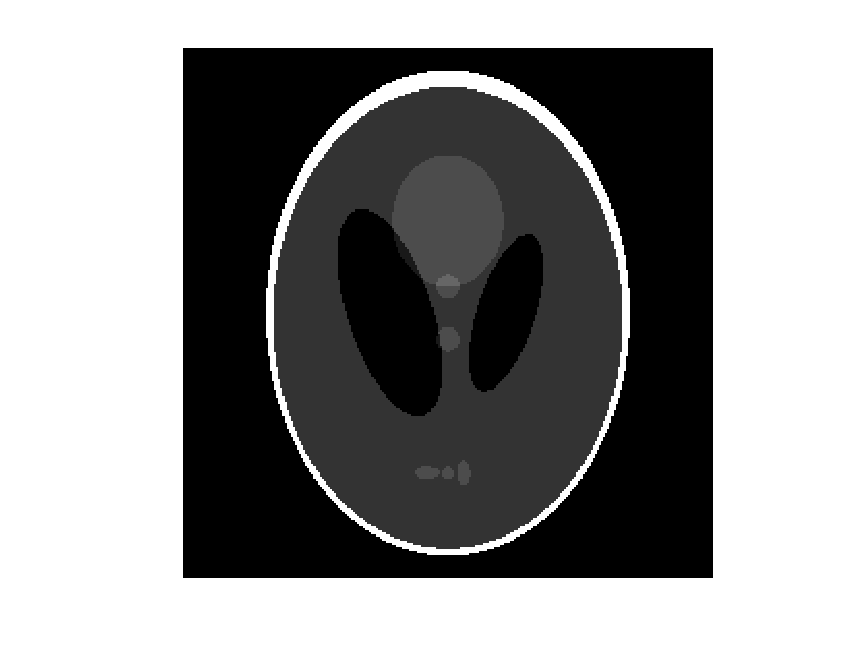

p = phantom(256);
imshow(p)

## Set up scan type

scan_type = "parallel";
if scan_type == "parallel"
    scan = @(x) radon(x,0:1:180); % default angle 0:1:180
    iscan = @(x) iradon(x, 0:1:180);
else
    scan = @(x) fanbeam(x, 250); % default distance 250
    iscan = @(x) ifanbeam(x, 250);
end

## Scan phantom

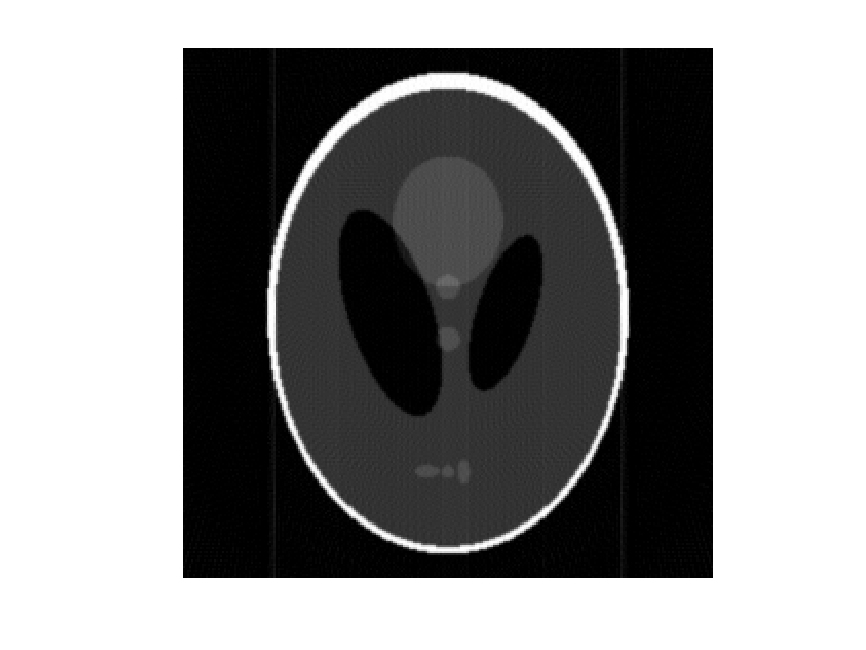

sinogram = scan(p);
imshow(iscan(sinogram))

## Simulate movement

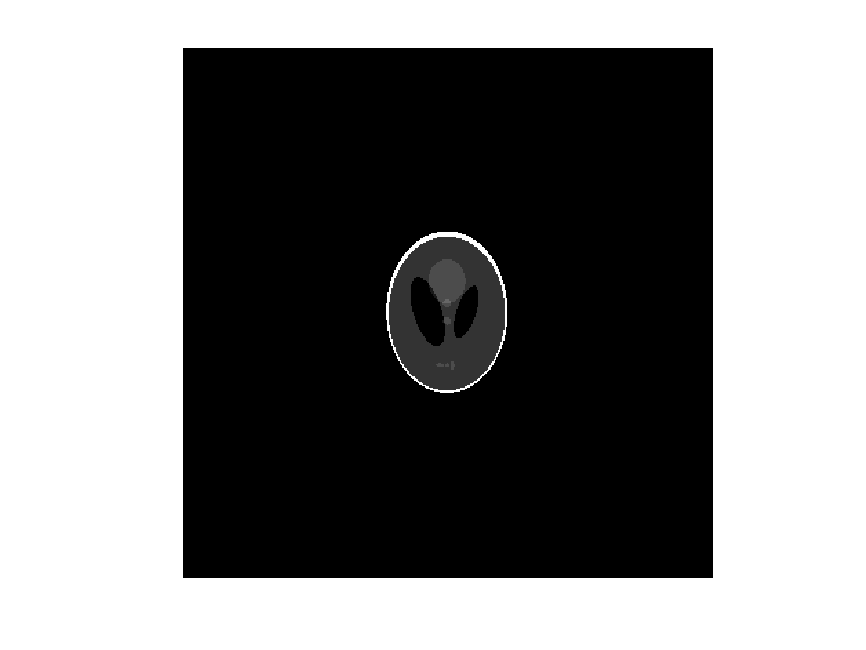

% generate a field in which the subject moves and/or rotate
field = zeros(size(p)*3);
xloc = length(field)/2; % where the subject locates in image
yloc = xloc;

imshow(draw(field, p, yloc, xloc))

initial_scan = scan(draw(field, p, yloc, xloc)); % create initial sinogram array matrix

for theta = 0:1:180
    img_temp = draw(field, p, round(yloc), round(xloc));
    scan_temp = scan(img_temp);
    initial_scan(:, theta+1) = scan_temp(:, theta+1);
    % xloc = xloc + 0.5; % motion along x-axis towards right
    % yloc = yloc + 1; % motion along y-axis downward
    p = imrotate(p, 0.1); % rotate the object by x angle
end

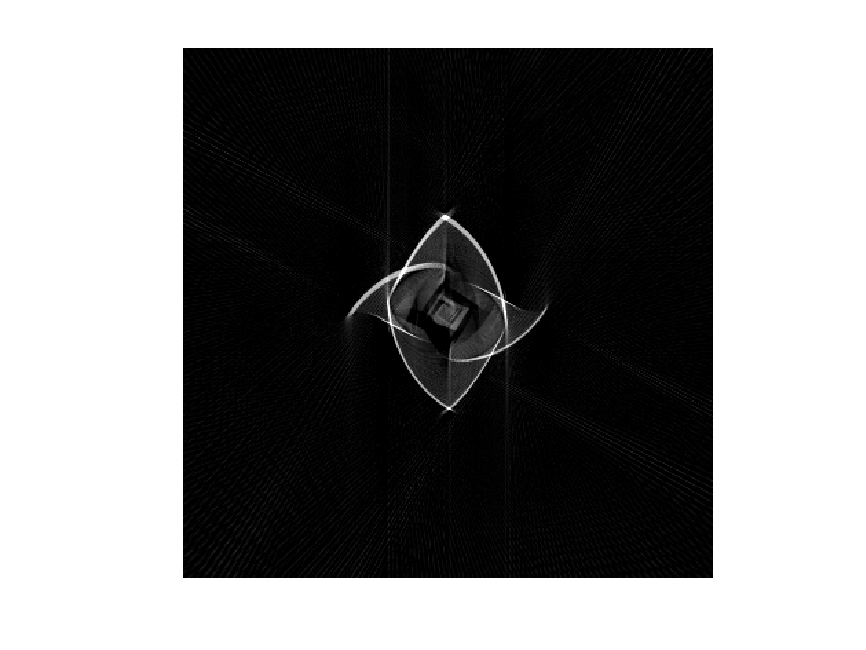


imshow(iscan(initial_scan))